%% Workspace cleanup
clear all
close all
clc 

%% Load of parameters
% mechanic transmission
mech.L   = 0.2;
mech.l   = 0.056;
mech.hp  = 0.082;
mech.H   = 0.179;
mech.Hp  = 0.019;
mech.hf  = 0.238;
mech.hfp = 0.042;

assert(abs(mech.hp+mech.H+mech.Hp-(mech.hf+mech.hfp)) < 1e-9, "experiment is unbalanced!");

% physics constants
const.g       = 9.80665;
const.rad2deg = 180/pi;
const.deg2rad = 1/const.rad2deg;
ozin2Nm       = 0.706e-2;

% H-bridge L293D motor drive
driver.kc = 1;
driver.Tc = 2e-9;

% Longruner Nema 17 17HS13-0404S stepper motor
stepper.La = 37e-3;
stepper.Ra = 30;
stepper.Vn = 12;
stepper.In = 0.4;
% holding torque is 36.8 oz.in.
stepper.tau_hold = 36.8 * ozin2Nm;
stepper.Km = stepper.tau_hold / stepper.In;
stepper.tausf = 0;
% rotor's diameter is 5 mm
stepper.rotor_r = 2.5e-3;
% rotor's inertia is 35 g cm^2
stepper.I = 35 * 1e-3 * 1e-2 * 1e-2; % Kg m^2
stepper.Jm = stepper.I / const.g;
stepper.Bm = 2.5e-7;
stepper.Nr = 100;
stepper.p = 2;
stepper.pp = stepper.Nr/stepper.p;
stepper.precision = 360/(stepper.p*stepper.Nr);
stepper.precision2 = stepper.precision/2;

stepper.Tstep = 5e-3;
stepper.Tstep2 = 5e-3;

stepper.Jeq = stepper.Jm;
stepper.Beq = stepper.Bm;

beam.m = 0.130;

% arduino
arduino.arch = 8;
arduino.vcc = 5;
arduino.gnd = 0;
arduino.adc.n_bits = 10;
arduino.adc.q_step = (arduino.vcc - arduino.gnd)/(2^(arduino.adc.n_bits));
arduino.adc.fc = 9615;

% HC-SR04 ultrasonic sensor
sensor.distance.Ts = 10e-3;

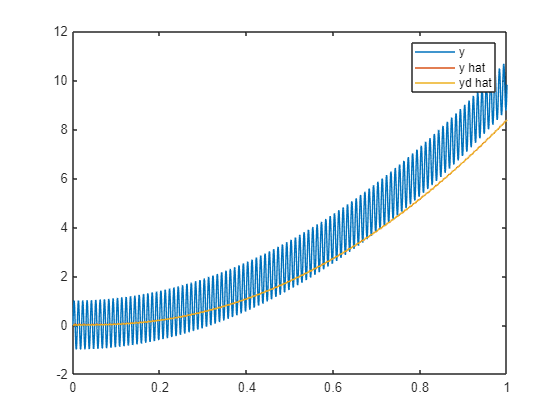

%% Filter
% actual signal (ball position)
t = 0:0.00001:1;
u = zeros(1,size(t,2));

for j = 1:size(u,2)
    u(1,j) = const.g * t(1, j)^2;
end

% noise
fc_noise = 1/sensor.distance.Ts;
e0 = sin(2 * pi * fc_noise * t);

% data creation
y = u + e0;

% digital acquisition data
td = 0:sensor.distance.Ts:1;
ud = zeros(1, size(td, 2));

for j = 1:size(ud, 2)
    ud(1, j) = const.g * td(1, j)^2;
end

% noise
e0d = sin(2 * pi * fc_noise * td);

% data creation
yd = ud + e0d;

% filtering
% mu0 = 2 * pi / sensor.distance.Ts;
mu0 = 2 * pi * 2;
s = tf('s');
H = mu0 / ( s + mu0 );
y_hat = lsim(H, y, t);

z = tf('z', sensor.distance.Ts);
Hd = mu0 * sensor.distance.Ts * (z + 1) / (z * (2 + mu0 * sensor.distance.Ts) + (-2 + mu0 * sensor.distance.Ts));
yd_hat = lsim(Hd, yd, td);
figure(1)
plot(t, y)
hold on
plot(t, y_hat)
plot(td, yd_hat)
legend("y", "y hat", "yd hat")

[ballnbeam.filter.num, ballnbeam.filter.den] = tfdata(Hd);
ballnbeam.filter.num = cell2mat(ballnbeam.filter.num);
ballnbeam.filter.den = cell2mat(ballnbeam.filter.den);
tmp = ballnbeam.filter.den(1);
ballnbeam.filter.a0 = ballnbeam.filter.den(1)/tmp;
ballnbeam.filter.a1 = -ballnbeam.filter.den(2)/tmp;
ballnbeam.filter.b0 = ballnbeam.filter.num(1)/tmp;
ballnbeam.filter.b1 = ballnbeam.filter.num(2)/tmp;

% ball
ball.m = 0.042;
ball.r = 0.021;
ball.I = 2/5 * ball.m * ball.r * ball.r;

request.Mp = 0.1;
request.ts = 5;

delta = log(1/request.Mp)/sqrt(pi^2 + log(1/request.Mp)^2);
wn    = 3/(delta*request.ts);

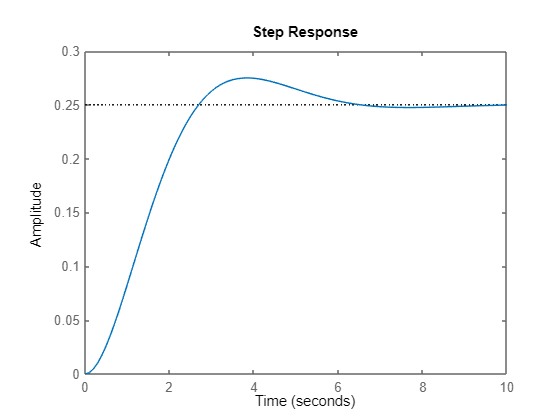

b2 = (ball.m*const.g)/(ball.I/(ball.r^2)+ball.m)*(mech.l/mech.L);
ballnbeam.A = [0 1; 0 0];
ballnbeam.b = [0; b2];
ballnbeam.C = [1 0];
ballnbeam.d = 0;
p1    = -delta*wn + 1i*wn*sqrt(1-delta^2);
p2    = conj(p1);
ballnbeam.controller.K = -place(ballnbeam.A, ballnbeam.b, [p1 p2]);

sys = ss(ballnbeam.A, ballnbeam.b, ballnbeam.C, ballnbeam.d);
gains = [ballnbeam.A ballnbeam.b; ballnbeam.C ballnbeam.d] \ [0;0;1];
ballnbeam.controller.Nx = [gains(1,1);gains(2,1)];
ballnbeam.controller.Nu = gains(3,1);
ballnbeam.controller.Nbar = -(ballnbeam.controller.Nu+ballnbeam.controller.K*ballnbeam.controller.Nx);
stable_sys = ss(ballnbeam.A+ballnbeam.b*ballnbeam.controller.K,ballnbeam.b,ballnbeam.C,ballnbeam.d);
figure(2)
step(0.25*ballnbeam.controller.Nbar*stable_sys,10)

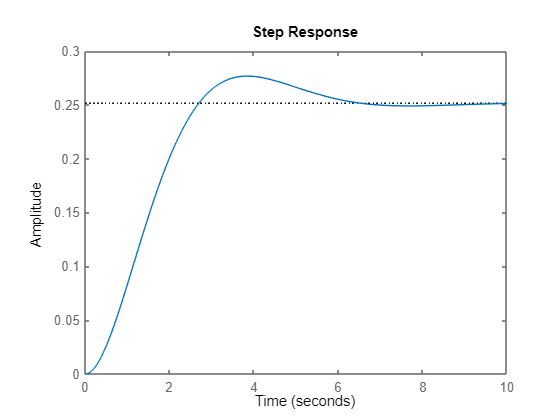

%% Digital
sysd = c2d(sys, sensor.distance.Ts, 'zoh');
ballnbeam.Ad = sysd.A;
ballnbeam.bd = sysd.B;
ballnbeam.Cd = sysd.C;
ballnbeam.dd = sysd.D;

p1d = exp(p1*sensor.distance.Ts);
p2d = exp(p2*sensor.distance.Ts);
ballnbeam.controller.Kd = -place(ballnbeam.Ad, ballnbeam.bd, [p1d p2d]);
stable_sysd = ss(ballnbeam.Ad+ballnbeam.bd*ballnbeam.controller.Kd,ballnbeam.bd,ballnbeam.Cd,ballnbeam.dd, sensor.distance.Ts);
figure(3)
step(0.25*ballnbeam.controller.Nbar*stable_sysd,10)

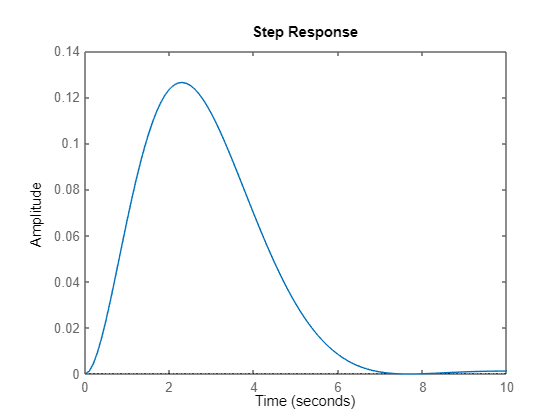

%% Robust tracking
ballnbeam.Ae = [0 ballnbeam.C; [0;0] ballnbeam.A];
ballnbeam.be = [0; ballnbeam.b];
ballnbeam.Ce = [0 ballnbeam.C];
ballnbeam.de = ballnbeam.d;

sigma = -delta * wn;
wd = wn * sqrt(1-delta^2);

p1 = sigma + 1i * wd;
p2 = sigma - 1i * wd;
p3 = sigma;

Ke = -place(ballnbeam.Ae, ballnbeam.be, [p3 p1 p2]);
ballnbeam.controller.Ki = Ke(1);
ballnbeam.controller.Ke = Ke(1, 2:3);
syse = ss(ballnbeam.Ae, ballnbeam.be, ballnbeam.Ce, ballnbeam.de);
stable_syse = ss(ballnbeam.Ae+ballnbeam.be*Ke,ballnbeam.be,ballnbeam.Ce,ballnbeam.de);
step(0.25*ballnbeam.controller.Nbar*stable_syse,10)

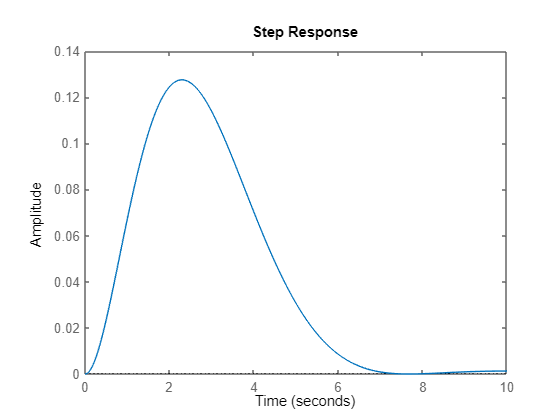

sysed = c2d(syse, sensor.distance.Ts, 'zoh');
ballnbeam.Aed = sysed.A;
ballnbeam.bed = sysed.B;
ballnbeam.Ced = sysed.C;
ballnbeam.ded = sysed.D;

p1d = exp(p1*sensor.distance.Ts);
p2d = exp(p2*sensor.distance.Ts);
p3d = exp(p3*sensor.distance.Ts);
Ked = -place(ballnbeam.Aed, ballnbeam.bed, [p3d p1d p2d]);
ballnbeam.controller.Kid = Ked(1);
ballnbeam.controller.Ked = Ked(1, 2:3);
stable_sysed = ss(ballnbeam.Aed+ballnbeam.bed*Ked,ballnbeam.bed,ballnbeam.Ce,ballnbeam.ded, sensor.distance.Ts);
figure(6)
step(0.25*ballnbeam.controller.Nbar*stable_sysed,10)

clear t
clear j
clear u
clear fc_noise
clear e0
clear y
clear ud
clear e0d
clear yd
clear mu0
clear H
clear Hd
clear yd_hat
clear y_hat
clear s
clear z
clear gains
clear Ke
clear Ked
clear delta
clear b2
clear p1
clear p2
clear p3
clear p1d
clear p2d
clear p3d
clear sigma
clear wn
clear wd
clear td
clear tmp
clear sys
clear sysd
clear syse
clear sysed
clear stable_sys
clear stable_sysd
clear stable_syse
clear stable_sysed